# Various functions for creating variables or simple operation

What we already deal with through previous sections,

- `zeros, ones`

- `cells`

- `sin, cos`

- `diag`

- `magic`

- `linspace`

- `isequal`

- matrix product, elementary-wise product

What we are going to learn in this section,

- `max, min, sort`

- `sum, mean, diff`

- `round, floor, ceil, fix`

- `rand, randi, randperm, randn, rng`

- `unique, histc`

- `size, numel, length`

Lastly, we will cover loops and conditional statements (For, If)

## `Max, Min, Sort`

[`M`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-M)` = max(`[`A`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-A)`)/min(`[`A`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-A)`)` returns the maximum/minimum elements of an array.

A = [1 9 -2; 8 4 -5; 3 1 6]

A =      1     9    -2
     8     4    -5
     3     1     6


max(A)

ans =      8     9     6


min(A)

ans =      1     1    -5


[`M`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-M)` = max(`[`A`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-A)`,[],`[`dim`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-dim)`)/min(`[`A`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-A)`,[],`[`dim`](https://www.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle#bubhhu5-1-dim)`)` returns the maximum/minimum element along dimension `dim`. For example, if `A` is a matrix, then `max(A,[],2)` is a column vector containing the maximum value of each row.

M = max(A,[],2)

M =      9
     8
     6


Dimension to operate along, specified as a positive integer scalar. If no value is specified, then the default is the first array dimension whose size does not equal 1.

Dimension `dim` indicates the dimension whose length reduces to `1`. The `size(M,dim)` is `1`, while the sizes of all other dimensions remain the same, unless `size(A,dim)` is `0`. If `size(A,dim)` is `0`, then `min(A,dim)` returns an empty array with the same size as `A`.

Consider a two-dimensional input array, `A`:

If `dim = 1`, then `min(A,[],1)` returns a row vector containing the smallest element in each column.

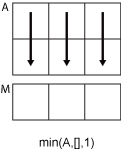

If `dim = 2`, then `min(A,[],2)` returns a column vector containing the smallest element in each row.

`min` returns `A` if `dim` is greater than `ndims(A)`.

Create a matrix `A` and compute the largest elements in each column, as well as the row indices of `A` in which they appear.

A

A =      1     9    -2
     8     4    -5
     3     1     6


M =      8     9     6


I =      2     1     3


[M,I] = max(A)

m =      1     1    -5


i =      1     3     2


[m,i] = min(A)

[`B`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-B)` = sort(`[`A`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-A)`)` sorts the elements of `A` in ascending order.

`[`[`B`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-B)`,`[`I`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-I)`] = sort(___)` also returns a collection of index vectors for any of the previous syntaxes. `I` is the same size as `A` and describes the arrangement of the elements of `A` into `B` along the sorted dimension. For example, if `A` is a vector, then `B = A(I)`.

A = randperm(10)

A =      8     1    10     4     2     9     7     3     5     6


B = sort(A)

B =      1     2     3     4     5     6     7     8     9    10


[B, I] = sort(A)

B =      1     2     3     4     5     6     7     8     9    10


I =      2     5     8     4     9    10     7     1     6     3


isequal(B, A(I))

ans = logical
   1


[`B`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-B)` = sort(`[`A`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-A)`,`[`dim`](https://www.mathworks.com/help/matlab/ref/sort.html?searchHighlight=sort&s_tid=srchtitle#bt8nojg-1-dim)`)` returns the sorted elements of `A` along dimension `dim`. For example, if `A` is a matrix, then `sort``(A,2)` sorts the elements of each row.

Create a matrix and sort each of its rows in ascending order.

A = [3 6 5; 7 -2 4; 1 0 -9]

A =      3     6     5
     7    -2     4
     1     0    -9


B = sort(A,2)           % sorts the elements of each row

B =      3     5     6
    -2     4     7
    -9     0     1


B = sort(A,'ascend')    % sort its columns in ascending order

B =      1    -2    -9
     3     0     4
     7     6     5


B = sort(A,2,'descend') % sort its rows in descending order

B =      6     5     3
     7     4    -2
     1     0    -9


## sum, mean, diff

`S = sum(`[`A`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-A)`)/mean(`[`A`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-A)`)` returns the sum/mean of the elements of A along the first array dimension whose size does not equal 1.

`S = sum(`[`A`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-A)`,`[`dim`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-dim)`)/mean(`[`A`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-A)`,`[`dim`](https://www.mathworks.com/help/matlab/ref/sum.html?searchHighlight=sum&s_tid=srchtitle#btv6ok6-1-dim)`)` returns the sum/mean along dimension `dim`. For example, if `A` is a matrix, then `sum``(A,2)` is a column vector containing the sum of each row.

A = 1:10;
S = sum(A)

S = 55

M = mean(A)

M = 5.5000

A = reshape(1:9,3,3)

A =      1     4     7
     2     5     8
     3     6     9


S = sum(A)

S =      6    15    24


M = mean(A)

M =      2     5     8


S = sum(A,2)

S =     12
    15
    18


M = mean(A,2)

M =      4
     5
     6


[`Y`](https://www.mathworks.com/help/matlab/ref/diff.html?searchHighlight=diff&s_tid=srchtitle#btwmxq8-1-Y)` = diff(`[`X`](https://www.mathworks.com/help/matlab/ref/diff.html?searchHighlight=diff&s_tid=srchtitle#btwmxq8-1-X)`)` calculates differences between adjacent elements of `X`

X = [1 1 2 3 5 8 13 21];    % fibonacci sequence
Y = diff(X)                 % this is same as the fibonacci sequence itself

Y =      0     1     1     2     3     5     8


A

A =      1     4     7
     2     5     8
     3     6     9


diff(A)     % For a 3-by-3 matrix, then compute the first difference between the rows.

ans =      1     1     1
     1     1     1


## round, floor, ceiling

`Y = round(`[`X`](https://www.mathworks.com/help/matlab/ref/round.html?searchHighlight=round&s_tid=srchtitle#buftmpz-X)`)` rounds each element of `X` to the nearest integer.

X = [-1.9 -3.4 1.6 2.5 -4.5 4.1]

X =    -1.9000   -3.4000    1.6000    2.5000   -4.5000    4.1000


Y = round(X)

Y =     -2    -3     2     3    -5     4


Round `pi` to the nearest 3 decimal digits.

round(pi,3)

ans = 3.1420

round(863178137,-2)

ans = 863178100

`Y = floor(`[`X`](https://www.mathworks.com/help/matlab/ref/floor.html?searchHighlight=floor&s_tid=srchtitle#bug_5mn-1-X)`)` rounds each element of `X` to the nearest integer less than or equal to that element.

Y = floor(X)

Y =     -2    -4     1     2    -5     4


`Y = ceil(`[`X`](https://www.mathworks.com/help/matlab/ref/ceil.html#bug2ukg-1-X)`)` rounds each element of `X` to the nearest integer greater than or equal to that element.

Y = ceil(X)

Y =     -1    -3     2     3    -4     5


`Y = fix(`[`X`](https://www.mathworks.com/help/matlab/ref/fix.html#bul3slv-X)`)` rounds each element of `X` to the nearest integer toward zero. 

Y = fix(X)

Y =     -1    -3     1     2    -4     4


## rand, randi, randperm, randn, rng

`X = rand(`[`n`](https://www.mathworks.com/help/matlab/ref/rand.html?searchHighlight=RAND&s_tid=srchtitle#buiavoq-1-n)`)` returns an `n`-by-`n` matrix of uniformly distributed random numbers.

`X = rand(`[`sz1,...,szN`](https://www.mathworks.com/help/matlab/ref/rand.html?searchHighlight=RAND&s_tid=srchtitle#buiavoq-1-sz1szN)`)` returns an `sz1`-by-...-by-`szN` array of random numbers where `sz1,...,szN` indicate the size of each dimension. For example, `rand``(3,4)` returns a 3-by-4 matrix.

r = rand(100)

r =     0.1576    0.4505    0.2077    0.6596    0.5309    0.5447    0.6126    0.9884    0.7400    0.1544    0.1841    0.2243    0.5864    0.3889    0.7202    0.2436    0.0249    0.8266    0.6153    0.9508    0.1629    0.4024    0.0573    0.0198    0.7604    0.9390    0.6535    0.2537    0.7603    0.1417    0.9816    0.7538    0.9469    0.8715    0.0667    0.8094    0.5179    0.5463    0.7203    0.0713    0.8246    0.2085    0.7512    0.2631    0.1230    0.8402    0.2497    0.6250    0.6595    0.3000
    0.9706    0.0838    0.3012    0.5186    0.6544    0.6473    0.9900    0.5400    0.2348    0.3813    0.7258    0.2691    0.6751    0.4547    0.3469    0.7851    0.6714    0.6769    0.3766    0.4976    0.8384    0.6589    0.6295    0.9643    0.8553    0.8154    0.4897    0.1326    0.5841    0.4379    0.4968    0.1319    0.5101    0.5076    0.5415    0.6088    0.2457    0.6366    0.6788    0.4891    0.7673    0.6658    0.4194    0.1027    0.5800    0.0708    0.4809    0.5676    0.2948    0

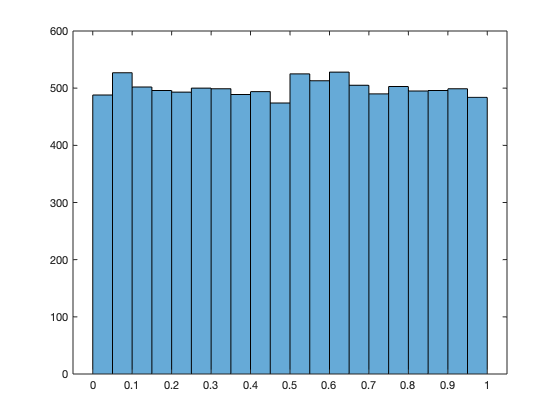

histogram(r)

`X = randi(`[`imax`](https://www.mathworks.com/help/matlab/ref/randi.html#buf2csg-imax)`)` returns a pseudorandom scalar integer between `1` and `imax`.

`X = randi(`[`imax`](https://www.mathworks.com/help/matlab/ref/randi.html#buf2csg-imax)`,`[`sz`](https://www.mathworks.com/help/matlab/ref/randi.html#buf2csg-sz)`)` returns an array where size vector `sz` defines `size(X)`. For example, `randi(10,[3,4])` returns a 3-by-4 array of pseudorandom integers between 1 and 10.

r = randi(10,5)

r =      1     3     9     3     1
     2     5     7     3     3
     8     2     4     7     5
     5     4     6     6     3
     4     3     3     1     7


`X = randi([`[`imin`](https://www.mathworks.com/help/matlab/ref/randi.html#buf2csg-imin)`,`[`imax`](https://www.mathworks.com/help/matlab/ref/randi.html#buf2csg-imax)`],___)` returns an array containing integers drawn from the discrete uniform distribution on the interval [`imin`,`imax`], using any of the above syntaxes.

Generate a 10-by-1 column vector of uniformly distributed random integers from the sample interval `[-5,5]`.

r = randi([-5,5],10,1)

r =      5
     3
     1
     3
     3
     1
     3
    -1
     1
    -3


`p = randperm(`[`n`](https://www.mathworks.com/help/matlab/ref/randperm.html#mw_09362558-0841-4b6e-9ea2-72634a543286)`)` returns a row vector containing a random permutation of the integers from 1 to `n` without repeating elements.

`p = randperm(`[`n`](https://www.mathworks.com/help/matlab/ref/randperm.html#mw_09362558-0841-4b6e-9ea2-72634a543286)`,`[`k`](https://www.mathworks.com/help/matlab/ref/randperm.html#mw_2a6fc12d-4a79-4bf4-b4b2-cb0278a3a8fe)`)` returns a row vector containing `k` unique integers selected randomly from 1 to `n`.

r = randperm(6)

r =      2     4     6     1     3     5


r1 = randperm(8,4)

r1 =      5     4     3     7


r2 = randperm(8,4)

r2 =      8     5     3     4


`X = randn(`[`n`](https://www.mathworks.com/help/matlab/ref/randn.html#bufqhx9-n)`)` returns an `n`-by-`n` matrix of normally distributed random numbers.

`X = randn(`[`sz`](https://www.mathworks.com/help/matlab/ref/randn.html#bufqhx9-sz)`)` returns an array of random numbers where size vector `sz` defines `size(X)`. 

r = randn(100)

r =     0.7923   -0.6327    0.2128    0.3545    0.3853   -0.1508    0.0856   -1.8151   -0.5435   -1.0841    1.5473   -0.4501   -0.3766   -1.1936   -1.3145    1.3703    1.4238    0.6053   -0.7660   -0.6918    1.2088    0.2003    0.1093   -1.3584   -0.4715    3.2289    1.6024    0.2985   -2.1486    0.2597   -0.8585    0.5125    1.0236    0.2081   -0.4262    0.9540   -1.4720    0.1527   -0.6396   -0.2936   -0.9184   -1.3430   -0.1709   -0.0559   -0.4646   -0.7022    1.0772    0.5492   -0.1396   -0.7873
   -0.3223   -1.2384    0.4681    1.8349   -0.3618   -0.4682   -0.5026   -0.8118    1.5722    1.2329    0.1670   -0.5658    0.7987    0.0401    0.5835   -1.0015   -0.4906    0.8615   -1.2700   -0.7237   -0.0925    1.4204    1.0577   -0.0441   -1.4850    0.4506    0.2576    1.0527   -0.5509    0.2434   -0.6010    1.3587   -0.0752   -0.3234   -0.1795    0.2962    0.4526   -0.1708   -0.4383    0.4826    0.6685   -1.2891    1.8750   -0.2659   -0.3899    0.1147   -1.0183   -0.0548   -1.1319    0

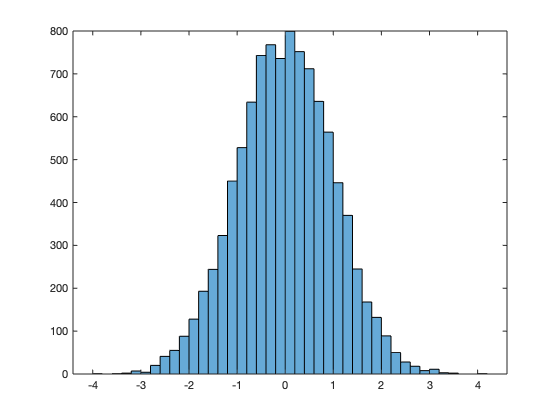

histogram(r)

Save the current state of the random number generator and create a 1-by-5 vector of random numbers.

s = rng;
r = randn(1,5)

r =    -0.8669   -2.6956    0.1428   -1.0275    0.5281


Restore the state of the random number generator to `s`, and then create a new 1-by-5 vector of random numbers. The values are the same as before.

rng(s);
r1 = randn(1,5)

r1 =    -0.8669   -2.6956    0.1428   -1.0275    0.5281


`rng(`[`seed`](https://www.mathworks.com/help/matlab/ref/rng.html#mw_8af805fc-011c-4d2a-9f2e-37c7eaf85518)`)` specifies the seed for the MATLAB random number generator. 

The `rng` function controls the *global stream*, which determines how the [`rand`](https://www.mathworks.com/help/matlab/ref/rand.html), [`randi`](https://www.mathworks.com/help/matlab/ref/randi.html), [`randn`](https://www.mathworks.com/help/matlab/ref/randn.html), and [`randperm`](https://www.mathworks.com/help/matlab/ref/randperm.html) functions produce a sequence of random numbers. To create one or more independent streams separate from the global stream, see [`RandStream`](https://www.mathworks.com/help/matlab/ref/randstream.html) and [`RandStream.create`](https://www.mathworks.com/help/matlab/ref/randstream.randstream.create.html).

Set the random number generator to the default seed (`0`) and algorithm (Mersenne Twister), then save the generator settings.

rng('default')
s = rng

s = 다음 필드를 포함한 struct :
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


x = rand(1,5)

x =     0.8147    0.9058    0.1270    0.9134    0.6324


rand(1,5)

ans =     0.0975    0.2785    0.5469    0.9575    0.9649


rng(s)
xold = rand(1,5)

xold =     0.8147    0.9058    0.1270    0.9134    0.6324


They are what we call 'pseudo-random' numbers.” The pattern can be made incredibly complex and difficult to identify, but at the end of the day `rng` isn't really random at all. For example, when we close MATLAB window and open, the first random numbers generated are always the same.

So, if we want to show the stimuli we showed to the participants in random order, we have to use the `rng('shuffle') `option.

The option initializes generator based on the current time, resulting in a different sequence of random numbers after each call to `rng`.

rng('shuffle')

ans = 4×3 table
              Age    Height    Weight
              ___    ______    ______

    Bob       38       64       131  
    Fred      38       71       176  
    George    40       67       185  
    Betty     43       69       163  


## unique, histcounts

[`C`](https://www.mathworks.com/help/matlab/ref/double.unique.html?searchHighlight=unique&s_tid=srchtitle#bs_6vpd-1-C)` = unique(`[`A`](https://www.mathworks.com/help/matlab/ref/double.unique.html?searchHighlight=unique&s_tid=srchtitle#bs_6vpd-1-A)`)` returns the same data as in `A`, but with no repetitions. `C` is in sorted order.

unique(A)
Name = {'Fred';'Betty';'Bob';'George';'Jane'};
Age = [38;43;38;40;38];
Height = [71;69;64;67;64];
Weight = [176;163;131;185;131];

A = 5×3 table
              Age    Height    Weight
              ___    ______    ______

    Fred      38       71       176  
    Betty     43       69       163  
    Bob       38       64       131  
    George    40       67       185  
    Jane      38       64       131  


A = table(Age,Height,Weight,'RowNames',Name)

C = 4×3 table
              Age    Height    Weight
              ___    ______    ______

    Bob       38       64       131  
    Fred      38       71       176  
    George    40       67       185  
    Betty     43       69       163  


C = unique(A)

[`N`](https://www.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=srchtitle#buijikm-1-N)` = histcounts(`[`C`](https://www.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=srchtitle#buijikm-1-C)`)`, where `C` is a categorical array, returns a vector, `N`, that indicates the number of elements in `C` whose value is equal to each of `C`’s categories. `N` has one element for each category in `C`.

`[`[`N`](https://www.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=srchtitle#buijikm-1-N)`,`[`edges`](https://www.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=srchtitle#buijikm-1-edges)`] = histcounts(`[`X`](https://www.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=srchtitle#buijikm-1-X)`)` partitions the `X` values into bins, and returns the count in each bin, as well as the bin edges. 

Distribute 100 random values into bins. `histcounts` automatically chooses an appropriate bin width to reveal the underlying distribution of the data.

X = randn(100,1);
[N,edges] = histcounts(X)

N =      2     2     7    16    18    24    20     5     6


edges =    -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000


histcounts(1:10)

ans =      1     1     1     1     1     1     1     1     1     1


X = [2 3 5 7 11 13 17 19 23 29];
N = histcounts(X)

N =      1     1     0     1     0     1     0     0     0     1     0     1     0     0     0     1     0     1     0     0     0     1     0     0     0     0     0     1


## size, numel

[`sz`](https://www.mathworks.com/help/matlab/ref/size.html?searchHighlight=size&s_tid=srchtitle#bvfgzsm-1-sz)` = size(`[`A`](https://www.mathworks.com/help/matlab/ref/size.html?searchHighlight=size&s_tid=srchtitle#bvfgzsm-1-A)`)` returns a row vector whose elements are the lengths of the corresponding dimensions of `A`.

[`szdim`](https://www.mathworks.com/help/matlab/ref/size.html?searchHighlight=size&s_tid=srchtitle#bvfgzsm-1-szdim)` = size(`[`A`](https://www.mathworks.com/help/matlab/ref/size.html?searchHighlight=size&s_tid=srchtitle#bvfgzsm-1-A)`,`[`dim`](https://www.mathworks.com/help/matlab/ref/size.html?searchHighlight=size&s_tid=srchtitle#bvfgzsm-1-dim)`)` returns the length of dimension `dim` when `dim` is a positive integer scalar. Starting in R2019b, you can also specify `dim` as a vector of positive integers to query multiple dimension lengths at a time. For example, `size``(A,[2 3])` returns the lengths of the second and third dimensions of `A` in the 1-by-2 row vector `szdim`.

A = rand(2,3,4,5);
whos A

  Name      Size               Bytes  Class     Attributes

  A         2x3x4x5              960  double              



sz = size(A)

sz =      2     3     4     5


szdim2 = size(A,2)

szdim2 = 3

`n = numel(`[`A`](https://www.mathworks.com/help/matlab/ref/double.numel.html#btl24wx-1-A)`)` returns the number of elements, `n`, in array `A`, equivalent to `prod(size(A))`.

A = magic(4);
A(:,:,2) = A'

A = A(:,:,1) =

    16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


A(:,:,2) =

    16     5     9     4
     2    11     7    14
     3    10     6    15
    13     8    12     1


n = numel(A)

n = 32

numel(1:10)

ans = 10

A = {'dog','cat','fish','horse'};
n = numel(A)

n = 4

# Loops and Conditional Statements

Within any script, you can define sections of code that either repeat in a loop or conditionally execute. Loops use a `for` or `while` keyword, and conditional statements use `if` or `switch`.

Loops are useful for creating sequences. For example, create a script named `fibseq` that uses a `for` loop to calculate the first 100 numbers of the Fibonacci sequence. In this sequence, the first two numbers are 1, and each subsequent number is the sum of the previous two, *F**n* = *F**n-1* + *F**n-2*.

N = 100;
f(1) = 1;
f(2) = 1;

for n = 3:N
    f(n) = f(n-1) + f(n-2);
end
f(1:10)

When you run the script, the `for` statement defines a counter named `n` that starts at 3. Then, the loop repeatedly assigns to `f(n)`, incrementing `n` on each execution until it reaches 100. The last command in the script, `f(1:10)`, displays the first 10 elements of `f`.

f

Conditional statements execute only when given expressions are true. For example, assign a value to a variable depending on the size of a random number: `'low'`, `'medium'`, or `'high'`. In this case, the random number is an integer between 1 and 100.

num = randi(100)
if num < 34
   sz = 'low'
elseif num < 67
   sz = 'medium'
else
   sz = 'high'
end

The statement `sz = 'high'` only executes when `num` is greater than or equal to 67.